# Optimizing Gemm

This Live Script helps you visualize the performance of the implementation of matrix-matrix multiplication.

To gather the performance data, execute 'make test_<your implementation>' in the command window.

clear

When completed, this creates output file 'output_data_GemmPJI_Ger.m' with timing data.  This Life Script then creates graphs from that timing data.

## Load timing data

It is important that in the below you enter the name of the output file created by your implementation.

output_data_Gemm_Parallel_Loop1_12x4
data_Loop1 = data_Gemm;
version_Loop1 = your_version;
MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

MaxAbsDiff = 7.9581e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



output_data_Gemm_Parallel_Loop2_12x4
data_Loop2 = data_Gemm;
version_Loop2 = your_version;
MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

MaxAbsDiff = 7.9581e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


output_data_Gemm_Parallel_Loop2_Opt_12x4
data_Loop2_Opt = data_Gemm;
version_Loop2_Opt = your_version;
MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end


output_data_Gemm_Parallel_Loop3_12x4
data_Loop3 = data_Gemm;
version_Loop3 = your_version;
MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

MaxAbsDiff = 7.9581e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


output_data_Gemm_Parallel_Loop3_Opt_12x4
data_Loop3_Opt = data_Gemm;
version_Loop3_Opt = your_version;
MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

MaxAbsDiff = 7.9581e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



% output_data_Gemm_Parallel_Loop4_12x4
% output_data_Gemm_Parallel_Loop5_12x4

## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This performance data is already computed in the fourth column of array "data_Gemm".

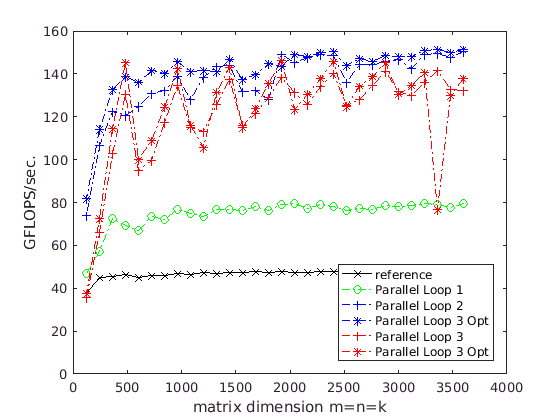

plot( data_ref( :, 1 ), data_ref( :, 3 ), 'k-x' );   % Plot the performance data for the reference implementation

hold all
 % Plot the performance data for your implementation implementation
plot( data_Loop1( :, 1 ), data_Loop1( :, 4 ), 'g-.o' ); 
plot( data_Loop2( :, 1 ), data_Loop2( :, 4 ), 'b-.+' ); 
plot( data_Loop2_Opt( :, 1 ), data_Loop2_Opt( :, 4 ), 'b-.*' );
plot( data_Loop3( :, 1 ), data_Loop3( :, 4 ), 'r-.+' ); 
plot( data_Loop3_Opt( :, 1 ), data_Loop3_Opt( :, 4 ), 'r-.*' ); 

xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS/sec.' );
legend( 'reference', ...
        version_Loop1, ...
        version_Loop2, ...
        version_Loop3, ...
        version_Loop3_Opt, ...
        'Location', 'SouthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero